load("ECG_template.mat");

fs = 500;  % Sampling frequency = 500 Hz
T = 1/fs;  % T= Sampling period

num_points = size(ECG_template, 2);
time_axis = linspace(0, T * (num_points-1), num_points);  %time axis from the frequency

snr = 5; %signal-noise ratio in decible
seed = 10;
nECG = awgn(ECG_template,snr,'measured',seed);

order = 3;
L = 11;
framelen = 2*L + 1;
sg310ECG = sgolayfilt(nECG,order,framelen);

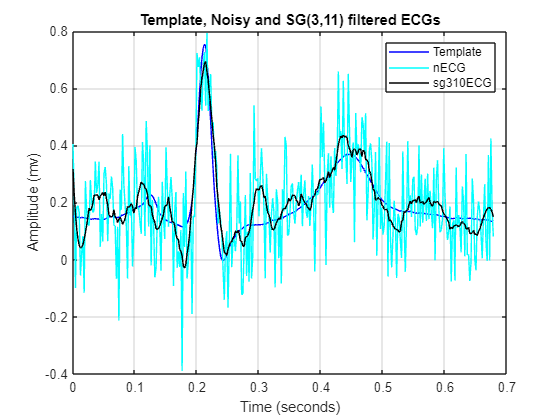

figure;
plot(time_axis, ECG_template,'b');
hold on;  
plot(time_axis, nECG, 'c');
hold on;  
plot(time_axis, sg310ECG, 'k');
xlabel('Time (seconds)');
ylabel('Amplitude (mv)');
title('Template, Noisy and SG(3,11) filtered ECGs');
legend('Template', 'nECG','sg310ECG');
hold off;
grid on;

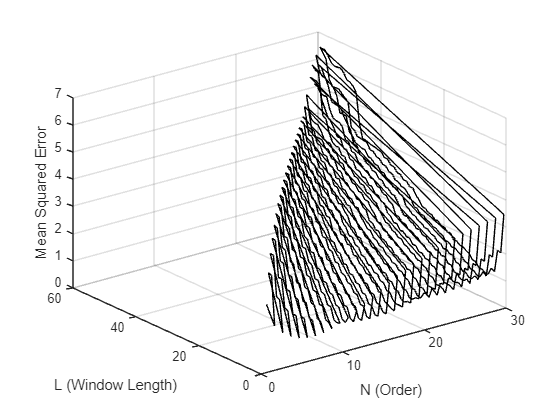

L_array = [];
N_array = [];
Errors_array = [];

for L = 1:30
    for N = 1:2*L-1
        order = N;
        framelen = 2*L + 1;
        sg_filtered = sgolayfilt(nECG,order,framelen);
        MSE = mean_squared_error(ECG_template,sg_filtered);
        
        L_array = [L_array, L];
        N_array = [N_array, N];
        Errors_array = [Errors_array, MSE];
    end
end

expand_dimension = length(Erros_array);
L_matrix = repmat(L_array, expand_dimension,1);
N_matrix = repmat(N_array, expand_dimension,1);
Errors_matrix = repmat(Errors_array, expand_dimension,1);

surf(L_matrix,N_matrix,Errors_matrix);
xlabel('N (Order)');
ylabel('L (Window Length)');
zlabel('Mean Squared Error');

min_Error = min(Errors_array);
min_L = L_array(Errors_array == min_Error);
min_N = N_array(Errors_array == min_Error);
fprintf('Minimum Error = %d, L= %d, N = %d)\n', min_Error, min_L, min_N)

Minimum Error = 7.756912e-01, L= 7, N = 1)


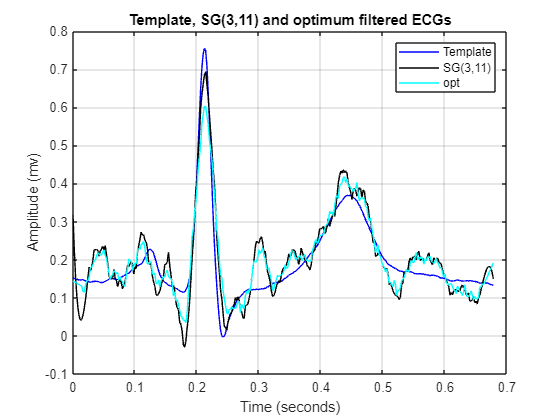

opt_order = min_N;
opt_L = min_L;
opt_framelen = 2*opt_L + 1;
opt_sg_ECG = sgolayfilt(nECG,opt_order,opt_framelen);

figure;
plot(time_axis, ECG_template,'b');
hold on;    
plot(time_axis, sg310ECG, 'k');
hold on;
plot(time_axis, opt_sg_ECG, 'c');
xlabel('Time (seconds)');
ylabel('Amplitude (mv)');
title('Template, SG(3,11) and optimum filtered ECGs');
legend('Template', 'SG(3,11)','opt');
hold off;
grid on;    